# **Building a GUM**

### **General call**

We'll review here how to create a model, the first step of the regression analysis.

This is usually done using the call `M = gum(T, fmla)` or `M = gum(T, fmla, opts)`, where `T `is a table storing the dataset to be analyzed, `fmla` is a string for the model formula, and `opts` is an optional structure for model options. We will cover how to write the formula below, so let's first treat what the fields of `opts` can be:

- `'observations'`: the distribution used for generating the response variable. Possible values are `'binomial' `(default; for binary response variables),` 'normal' `(for continuous response variables)`, 'poisson' `or` 'neg-binomial' `(both for count response variables). `'neg-binomial' `allows to capture over-dispersed data, i.e. when the variance of the count data is larger than the expected mean of the count data, which frequently arises e.g. in neuron spiking data.

-  '`link`': link function. By default, the canonical link function is used (`'logit'` for binomal observations; '`identity`' for normal observations; '`log`' for Poisson and neg-binomial observations). The only other possible value is '`probit`' for binomial observations.

- '`w'`: a vector of observations weights, i.e. how much each observation should count towards estimating a model. For example if some observations are repeated, use the number of repetitions in `'w'.`

- `'label`': label for the model (a string or character array)

- `'prior'`: set to `'none'` to remove all priors over model weights and adopt a frequentist approach (see Priors on weights)

#### Alternative syntax

Alternatively, a model can be declared using the syntax `M = gum(X, y)` or `M = gum(X, y, opts)`, where `X` is a predictor matrix (i.e. matrix of regressors) and `y` is a vector of responses (or output variable). `X` and `y` should have the same number of rows corresponding to the number of observations. In the case of binary observations, `y` may also be a two column matrix, the first column containing the number of successes for each observation, and the second containing the total number of trials. `opts` accepts the same arguments as for the other syntax, and also accepts field `'constant'` to decide whether a regressor of ones is included (to capture the intercept). Possible values are `'on'` [default] and `'off'.`

For more complex models, `gum` can also take a regressor object `R `(or array of regressors) as input instead of X. Regressor objects are created using the call `R = regressor(X,type, ...)` and can be composed using standard operations such as `R = R1 + R2`, `R = R1*R2` or `R = R1*(R2+R3)`. Type `help regressor` for help on how to build them. This syntax should be reserved to `GUM `models that cannot be build using formula type, so likely not for the average user.

#### **Basic syntax for formulas**

Ok, let's now go to the interest part: how to write the model formula! Basic formula should be straightforward if you are used to writing R-style formulas (as in R, in matlab using functions such as `fitglm` or `fitlme, `in Python's `statsmodel`, etc.). `gum` offers some extended possibilities for formulas that we will cover step by step, but let's start with the basics. Each formula starts with a declaration of the type `y ~ ...`, where `y `is the response variable (or dependent variable, or output variable), i.e. the variable we want to predict from other variables. What comes to the right is a formula made up of regressor variables and operations (additions, multiplications, parentheses) that describe the functional form of the predictor. It's crucial that you think hard about what is the functional form that suits your analysis, i.e. **how you expect the different regressions to interact** when producing the dependent variable. The response variable as well as all regressor variables should be variables in the table.

There are two alternative ways of defining the response variable:

- `ySuccess / yTotal ~ ...` where `ySuccess` contains the number of successes for each observation, and  `yTotal` contains the total number of trials (for binary observations). 

- `y | c ~ ...` where `c` is a categorical variable to split the dataset based on the values of `c` and estimate the model independently for each dataset. See more in the population tutorial.

#### **Formulas for a GLM**

Let's us start with formulas for the Generalized Linear Model (GLM). The possible syntax we will cover in this section feature:

- continuous regressors: `x`

- categorical regressors: `cat(x)`

- including the intercept or no: `+1` or `+0`

- including a fixed regressor: `[x]`

- splitting a (set of) regressors by a categorical variable: `x|z`

- lagged regressors: `lag(x) or lag(x;Lags=1:n)`

We will use the same dataset as in [getting_started.mlx](matlab:open('getting_started.mlx')). A monkey decides on each trial whether a motion in a complex visual stimulus is more towards the left or right. Throughout the tutorial we will build  models that predict the response of animal based on different regressors.

T = load_online_dataset();

loading csv file from url...done


head(T)

    resp    target    session     Stimulus     Stimulus1    Stimulus2    Stimulus3    Stimulus4    Stimulus5    Stimulus6    Stimulus7    accuracy     response    trial
    ____    ______    _______    __________    _________    _________    _________    _________    _________    _________    _________    _________    ________    _____

     0        0          1       1×7 double       -10           -9          -10           -7          -13          -12          -11       "correct"       -1         1  
     0        0 

We can define a simple GLM (logistic regression) with **continuous regressors** using a formula `y ~ x1 + x2 + ...` Here we capture the impact on choice of each of the 7 motions pulses that compose the stimuli using the formula.

fmla = 'resp ~ Stimulus1 + Stimulus2 + Stimulus3 + Stimulus4 + Stimulus5 + Stimulus6 + Stimulus7';
M = gum(T, fmla);

We can estimate weights and plot them using the following call (more about this in other tutorials):

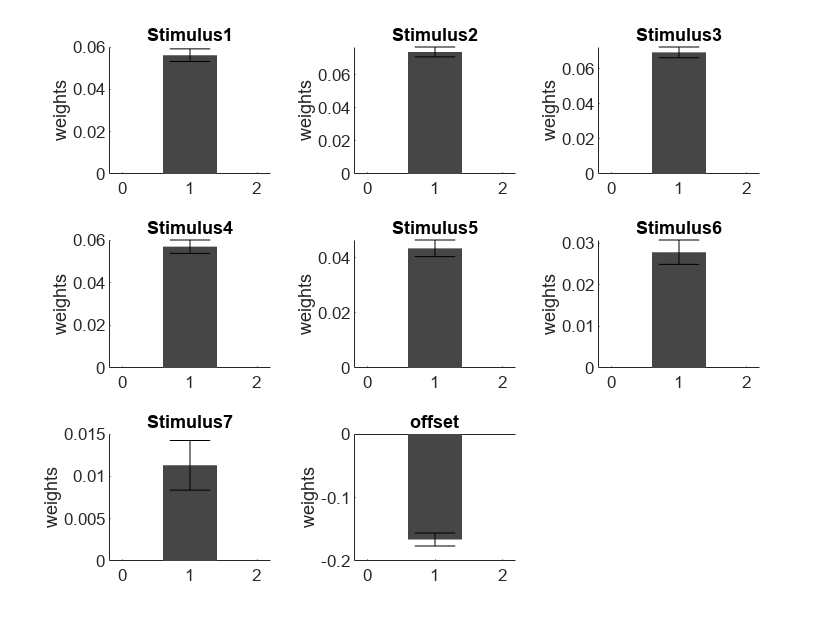

Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-29669.900812
Computing posterior covariance...done


figure;
M.infer().plot_weights();

You can see a the weight of each of the regressors, and also of the intercept which is automatically added.

We make a simple change to the formula by adding parenthesis around the regressors. This only affects plotting: now all weights for the stimulus pulses are plotted in the same plot. Much cleaner:

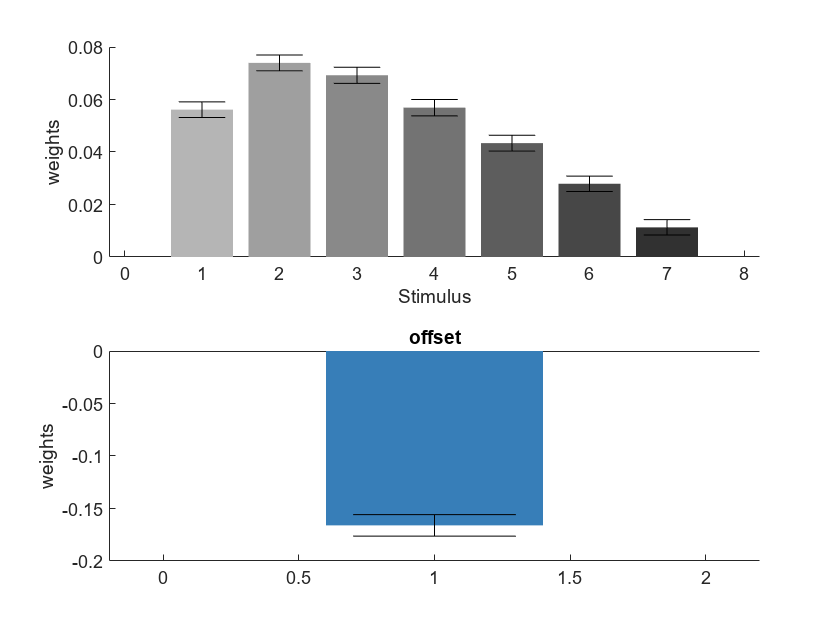

Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-29669.900812
Computing posterior covariance...done


fmla = 'resp ~ (Stimulus1 + Stimulus2 + Stimulus3 + Stimulus4 + Stimulus5 + Stimulus6 + Stimulus7)';
M = gum(T, fmla);
figure;
M.infer().plot_weights();

You can also add **multiple valued variables**. Here we have inserted a variable `Stimulus` in the table which simply concatenates for each trial the value of `Stimulus1, ... Stimulus7. `We can add this variable into the formula instead of all 7 variables, and see that this creates exactly the same regression model:

Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-29669.900812
Computing posterior covariance...done


fmla = 'resp ~ Stimulus';
M = gum(T, fmla);
figure;
M.infer().plot_weights();

#### Including the intercept (or not)

Here you see that the intercept is automatically included in the regression model. You can specify if you don't want to include this by adding `+0 `to the formula. Note that the formula `'resp ~ Stimulus+1' `is equivalent to just `'resp ~ Stimulus'` (including an intercept is the default behavior).

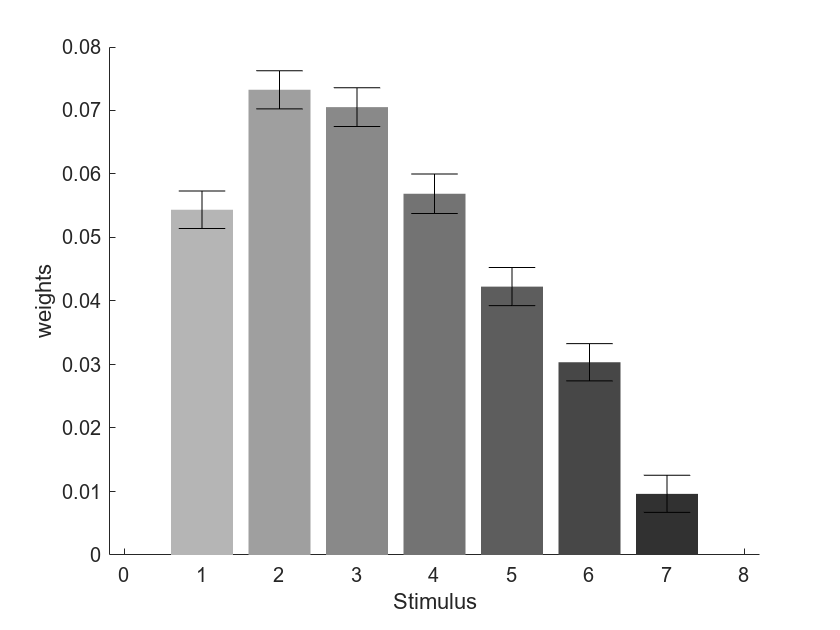

Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-29802.374585
Computing posterior covariance...done


fmla = 'resp ~ Stimulus + 0';
M = gum(T, fmla);
figure;
M.infer().plot_weights();

#### Categorical variables

To add a **categorical variable**, use the `cat(x)` syntax. For example we can incorporate the impact of the experimental session on the lateral bias (the tendency of the animal to respond more to the left or to the right) by including regressor `cat(session)`. Note that if the class of variable `x` is categorical, then `x `is equivalent to `cat(x)`. 

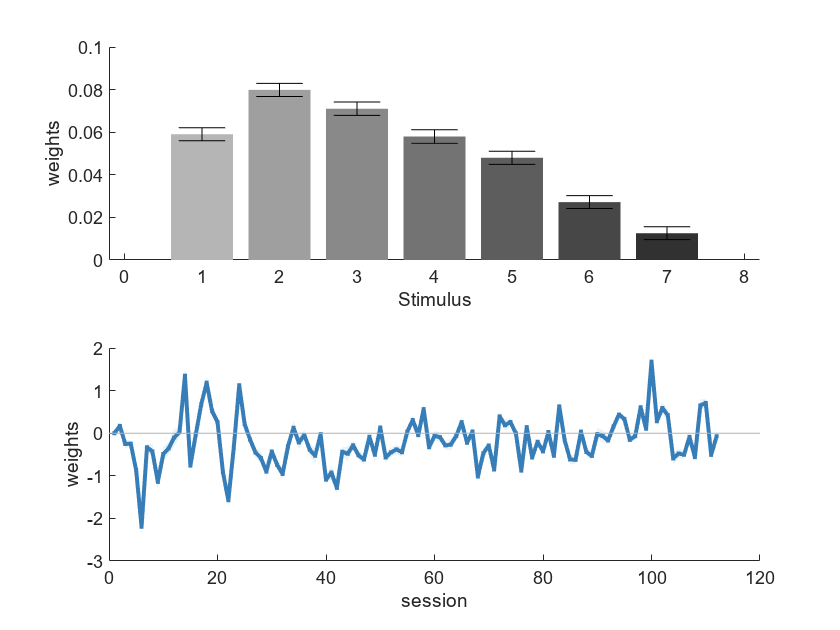

fmla = 'resp ~ Stimulus + cat(session) + 0';
M = gum(T, fmla);
figure;
M = M.infer('verbose','off');
M.plot_weights();

#### Interactions

You can interaction terms between continuous or categorical regressors using the `: `operator. For example, `x1:x2` captures the interaction term between regressors `x1` and `x2. `Use the `^ `operator to include main effects and interaction times (we do not use `*` as traditionally because in gums `*` capture products of regressors, which we cover later in the tutorial).

You can also include a variable as a **fixed offset **using the syntax `[x]`.  

#### Splitting regressors 

You can build a set of regressors by **splitting a regressor** `x `(or a set of regressor) based on the value of a categorical variable `z `using the syntax `x|z`. For example one can estimate separate sets of weights for each session by using (we restrict our analysis here of the first 3 sessions):

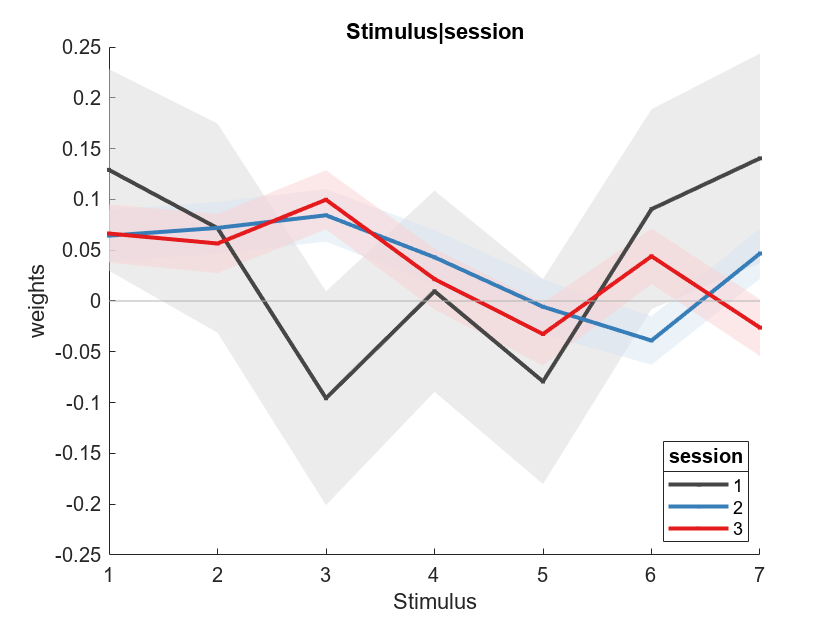

fmla = 'resp ~ Stimulus|session + 0';
M = gum(T(T.session<=3,:), fmla);
figure;
M = M.infer('verbose','off');
M.plot_weights();

#### Lagged regressor

Finally you can introduce lagged regressor, i.e. regressors that are shifted by one or more observations, by using `lag(x).` This is especially useful to capture statistical dependenies across time, when observations represent successive events (such as here trials in a behavioral experiment). `lag(x)` represents the value of variable `x` on the previous observation, while `lag(x; Lags=1:n)` creates a set of *n *regressors, each representing the variable `x` with a certain lag between 1 and *n. *Check out more details about how to create lagged regressors on our dedicated tutorial. For example we can test whether the animal displays a tendency to respond more to the same side as in previous 5 trials using the following model:

fmla = 'resp ~ Stimulus  + lag(response; Lags=1:5)';
M = gum(T, fmla);
figure;
M = M.infer();

Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-29645.683040
Computing posterior covariance...done


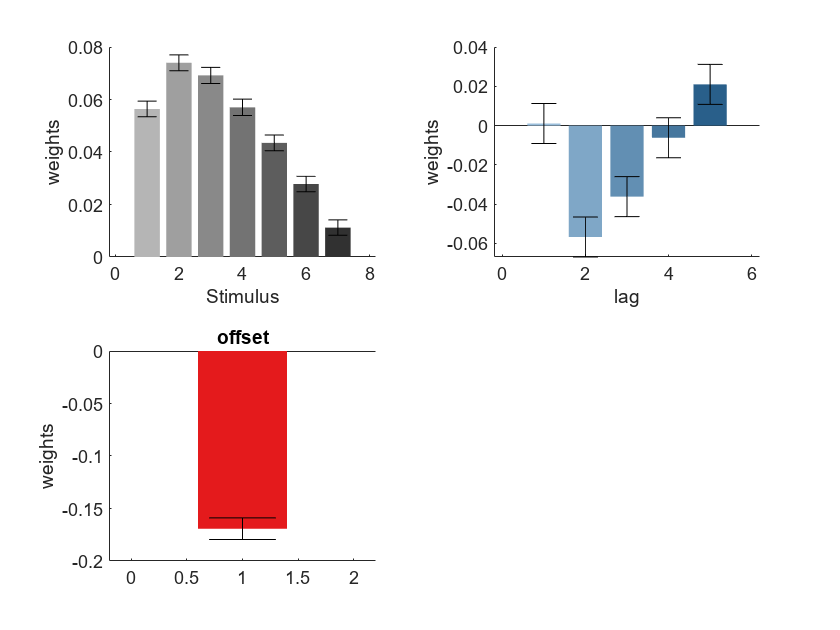

M.plot_weights();

### **Priors on weights**

By default, GUM adopts a Bayesian perspective of regression. This means that weights $w$  of model *M *are associated with a certain prior $p(w)$ which is a multivariate gaussian. This is combined with the likelihood of the data $p_M(y|X,w)$ to compute an approximate posterior $p_M(w|X,y)$ which is also a gaussian distribution. This also allows to compute an approximate model evidence (or marginal evidence) $p_M(y|x) = \int_w p(w) p_M(y|X,w)dw$, which can be used for model selection.  For GLMs, by default the prior over weights is the standard gaussian, i.e. independent normal distribution with zero mean and unit variance.

You can change to a frequentist approach (i.e. remove all priors on weights) by adding the field `'prior' `in `opts` with value `'none':`

fmla = 'resp ~ Stimulus';
opts = struct('prior','none','label','no prior');
M(1)= gum(T(1:30,:), fmla, opts);

You can change also remove the prior of a single regressor (or set of regressors) `x `by using the syntax `x(prior=none)` in the formula. For example, `fmla = 'Stimulus(prior=none) + cat(session)'` creates a model where the stimulus weights have no prior while the session weights have a gaussian prior.

#### Setting up the prior on weights (Bayesian regression)

The variance of the gaussian prior can be adjusted by using the syntax `x(variance=V)` where `V` is a value. For example, here we set the variance to 0.1 (we expect weights to be on the order of magnitude of $\sqrt{0.1} \approx 0.31$):

fmla = 'resp ~ Stimulus(variance=0.1)';
M(2)= gum(T(1:30,:), fmla,'label','variance 0.1');

Let us compare these two models to the standard model with unit variance. We're doing it on a reduced set of 30 trials so that the impact of the prior is increased. We can see indeed that the no-prior weights are larger in amplitude compared to the unit variance model, and the model with reduced prior variance on stimulus weights display even smaller stimulus weights.

fmla = 'resp ~ Stimulus';
M(3)= gum(T(1:30,:), fmla, 'label','standard');
M = M.infer(); % estimate weights for all three models

Inferring weights for model 1/3:  no prior ()
Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-12.209611
Computing posterior covariance...done

Inferring weights for model 2/3:  variance 0.1 ()
Evaluating prior covariance matrix...done
****x
converged after 5 iterations, log-joint:-12.995961
Computing posterior covariance...done

Inferring weights for model 3/3:  standard ()
Evaluating prior covariance matrix...done
****x
converged after 5 iterations, log-joint:-12.995961
Computing posterior covariance...done



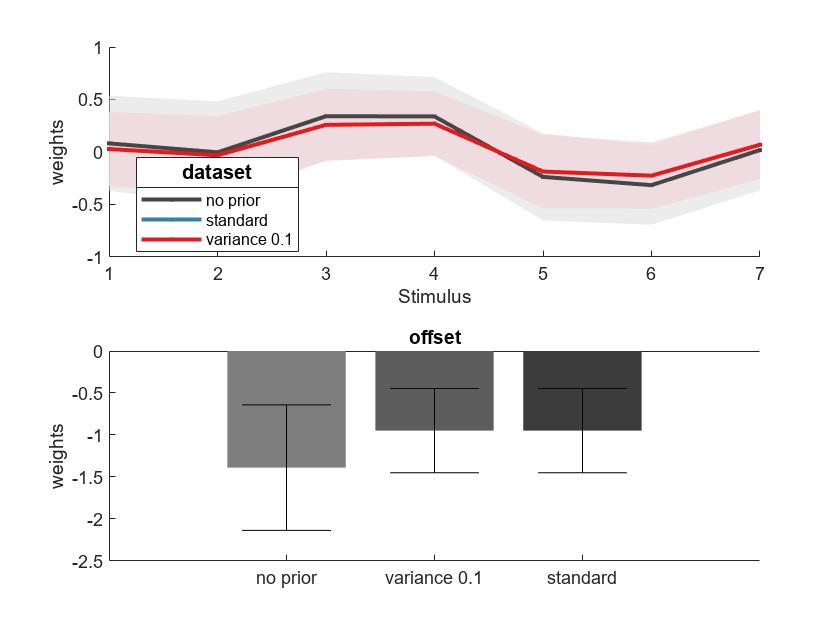

Mc = M.concatenate_over_models; % concatenate results in a single model object for plotting
figure; Mc.plot_weights;

#### Fitting the variance hyperparameter  (Empirical Bayes)

The variance of the prior can be fitted to data using the command `fit()` instead of `infer(). `Find out more about the different types of priors, hyperparameters that control the prior and how to fit them to data in the dedicated tutorial.

### **Including nonlinear mapping**

Oftentimes we want to capture the impact of a continuous variable $x$ and cannot assume *a priori *that this impact is linear in $x$. So we would like to capture contributions to the predictor in the form of $f(x)$ where $f$ is an unknown function we want to estimate from the data. This problem is usually known as Generalized Additive Models (GAM). In the GUM toolbox, you can include them simply by including regressors of the form `f(x) `to your formula. For example, to include a model where $x$ has a nonlinear impact while $z$ has a linear impact on the predictor, write the formula as `'y ~ f(x) + z'`. Nonlinear mapping can be treated in two different ways: using basis functions or Gaussian Processes. We start with basis functions because it is probably more intuitive, but Gaussian Processes are more powerful and are the default option. A more complete description of how to declaring nonlinear mapping is available in the [dedicated tutorial](matlab:open('./nonlinear_mapping.mlx')).

#### Basis functions

When using **basis functions**, we basically constrain the function $f$ to take the form $f(x) = \sum_k \beta_k b_k(x)$ where $b_k$ are a set of fixed basis functions. For example if we use polynomials, then $b_0(x) = 1$, $b_1(x)=x$, $b_2(x)=x^2$, and so on. You can declare a nonlinear mapping with basis function using the syntax `f(x; basis=str)` or `str(x) `where `str` is the name of a basis function. For example `str=poly3` will give you polynomials of order 2 (so $b_0(x) = 1$, $b_1(x)=x$, $b_2(x)=x^2$, $b_3(x)=x^3$), e.g. will estimate a cubic function.

In our example let's try to capture the change in animal lateral bias across session using a cubic function of session. 

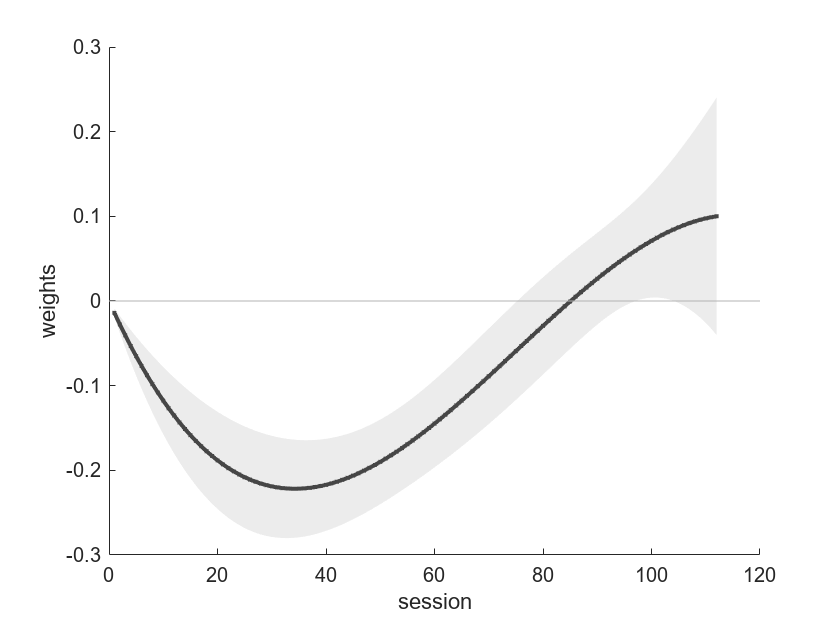

subset = 1:20:height(T); % just one every 20 trials - we actually have enough statistical power to estimate this bias precisely on each session if we use the full data
M = gum(T(subset,:), 'resp ~ poly3(session)');
figure;
M.infer('verbose','off').plot_weights;

You can visualize the set of basis functions using `plot_basis_functions`:

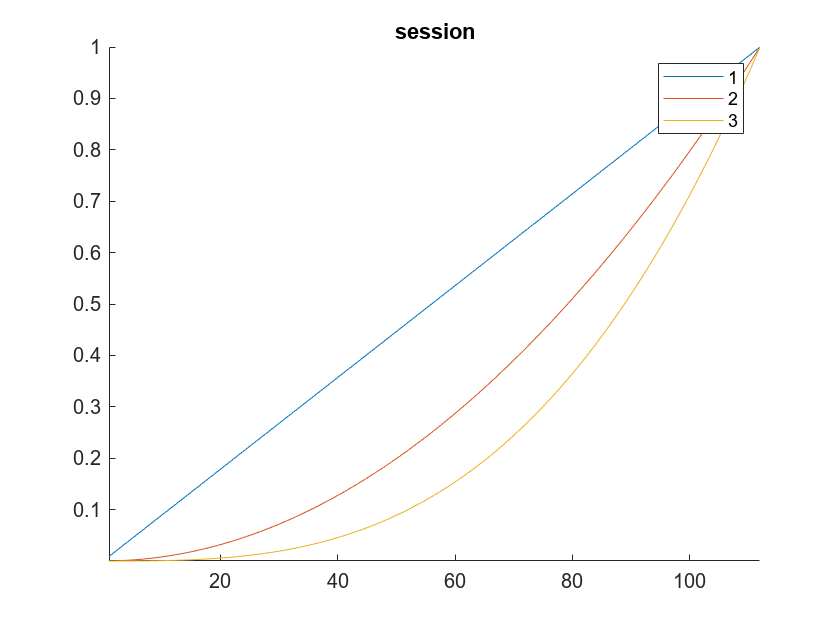

figure;
M.plot_basis_functions([],'normalize'); % we use the normalize option because otherwise x^3 takes on much larger values

The set of basis functions you can use include polynomials, exponentials, gamma distributions and raised cosines. By defaults, weights for the basis functions $\beta_k$ have gaussian prior - see more details in the tutorial about [nonlinear mapping](matlab:open('./nonlinear_mapping.mlx')).

#### Gaussian Processes

The other framework for capturing nonlinear mapping is Gaussian Processes. This is what is applied by default, if we simply define the function in our formula by `f(x)`. In Gaussian Processes, we do not define a set of basis functions, or rather we use an infinite set of basis functions. The magic of Gaussian Processes lies is that it imposes a prior over function evaluations $f(x_i)$ that constrains the inferred function to be smooth. This prior depends on two hyperparameters: a variance parameter (`variance`) and a scale parameter (`tau`), here set at their default values:

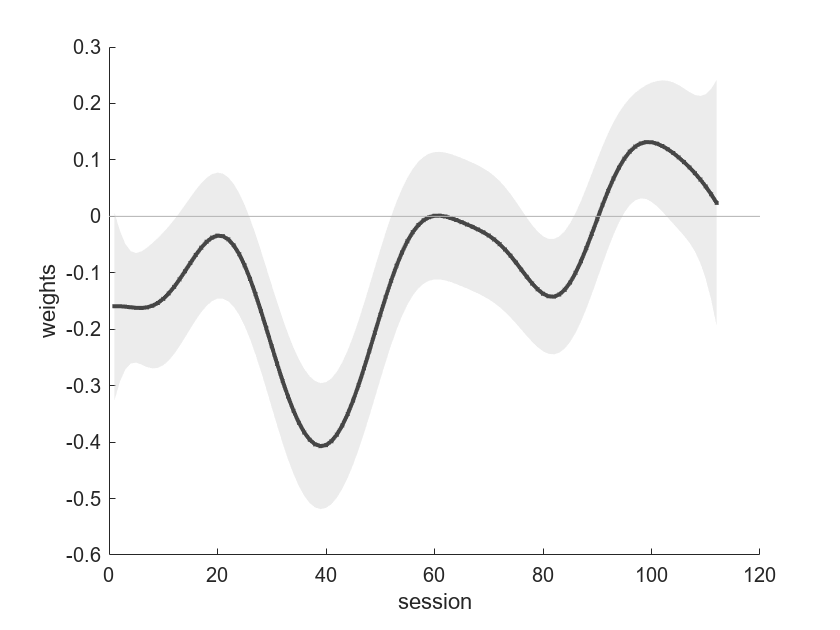

M = gum(T(subset,:), 'resp ~ f(session) + 0');
M = M.infer('verbose','off'); % infer all models at once
figure; M.plot_weights;

Fitting the hyperparameters for variance and scale to the data is done using `M.fit()` instead of `M.infer()`.

Check the [dedicated tutorial](matlab:open('./nonlinear_mapping.mlx')) for an in-depth coverage about non-linear mappings in GUM.

### **Products of regressors**

One unique feature of the GUM toolbox is the ability to include product of regressors in the predictor formula such as `f(x)*f(y)`. This allows to capture a richer set of regression problems than the typical Generalized Linear Models or Generalized Additive Models. This is helpful in general when we want to **test whether one variable modulates the impact of another. ** We illustrate here with a model with two sets of regressor products:

-  the first set will capture the *impact of the stimulus sequence and its modulation across sessions*. This is written in the formula as `Stimulus*f(session). `The first term `Stimulus` captures the linear effect of the stimulus sequence (`Stimulus` is a 7-element array, so the model will estimate a 7-element vector of weights). The second term `f(session) `captures the nonlinear modulation by session identity  - this could be replaced by `cat(session) `if we don't expect this impact to vary smoothly across sessions. [Note: here we only expect the impact of the stimulus to vary in amplitude across sessions but not in shape (e.g. we cannot capture a change across sessions from weighting the first stimuli in the sequence to weighting the last). That would require fitting a different set of weights in each session using `Stimulus|session`, which require a much larger statistical power.]

- the second set will capture the *impact on current response of recent history* (history of last 6 responses), *modulated again across sessions*. This is in written in the formula by  `lag(response;lags=1:6)*f(session)`, where the term before the multiplicative sign encodes for the history effect and the term after the multiplicative sign encodes for the impact of session.

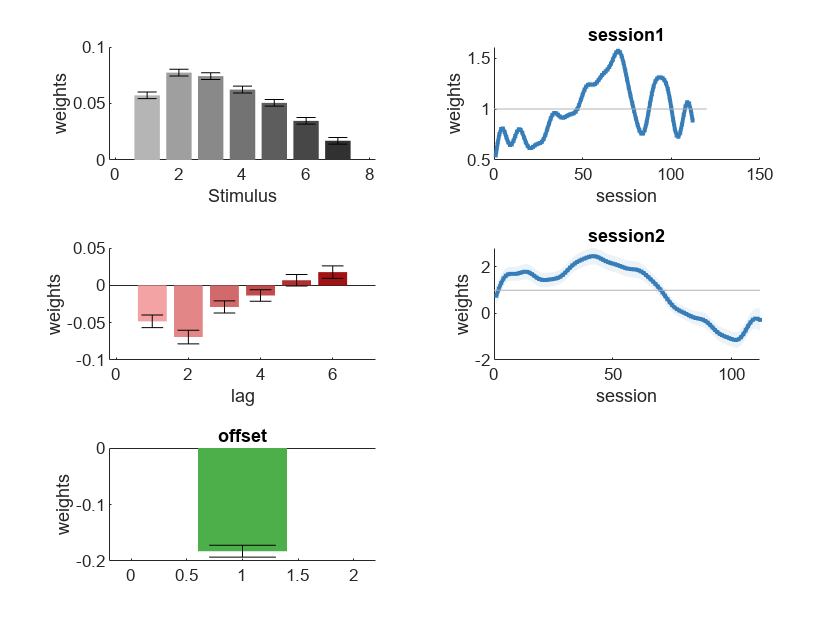

Evaluating prior covariance matrix...done
Fitting weights, starting point 1/10
****x*>>>o
converged after 10 iterations, log-joint:-29022.110210
Fitting weights, starting point 2/10
****x***>o>>
converged after 12 iterations, log-joint:-29022.110210
Fitting weights, starting point 3/10
****x***>o>>
converged after 12 iterations, log-joint:-29022.110210
Fitting weights, starting point 4/10
****x***>o>>
converged after 12 iterations, log-joint:-29022.110210
Fitting weights, starting point 5/10
****x*>**o>>>>x>>>>O
converged after 20 iterations, log-joint:-29022.110210
Fitting weights, starting point 6/10
****x****o>>
converged after 12 iterations, log-joint:-29022.110210
Fitting weights, starting point 7/10
****x****o*>>>
converged after 14 iterations, log-joint:-29022.110210
Fitting weights, starting point 8/10
****x****o>>>
converged after 13 iterations, log-joint:-29022.110210
Fitting weights, starting point 9/10
****x****o>>
converged after 12 iterations, log-joint:-29022.110210
Fitt

M = gum(T, 'resp ~ Stimulus*f(session) + lag(response;lags=1:6)*f(session)');
figure;
M.infer.plot_weights;

It crucial to understand how this set of weights are interpreted. Here the blue curve (Session 1) shows the modulation of the impact of the stimulus across sessions, with an increase until session 70 (i.e. the animal performance improves over sessions), followed by non-monotonic fluctuations. The green curve shows the impact of the recent history of choices changes across sessions, being more or less constant until session 60 and decreasing afterwards (with even a change of sign).

#### Constraints on weights

Oftentime we have to introduce some constraints on the set of weights in order to make the problem identifiable, that is to make sure that there is only set of weights that maximizes the likelihood of the data. GUMs can suffer from two types of identifiability problems: invariance to offset and invariance to scale. Invariance to offset occurs for example if we define the predictor using a formula $\rho = f_x(x) + f_y(y)$. Then, for a given pair of functions $(f_x,f_y)$, I can substract some fixed value $z$ from $f_x$ and add it to $f_x$ get exactly the same $\rho$ (because $(f_x(x)-z) + (f_y(y)+z)=f_x(x)+f_y(y)$ ). This is illustrated here with $f_x=x^2$, $f_y = \cos(y)$ and $z=1$: the two subplots on the bottom are identical.

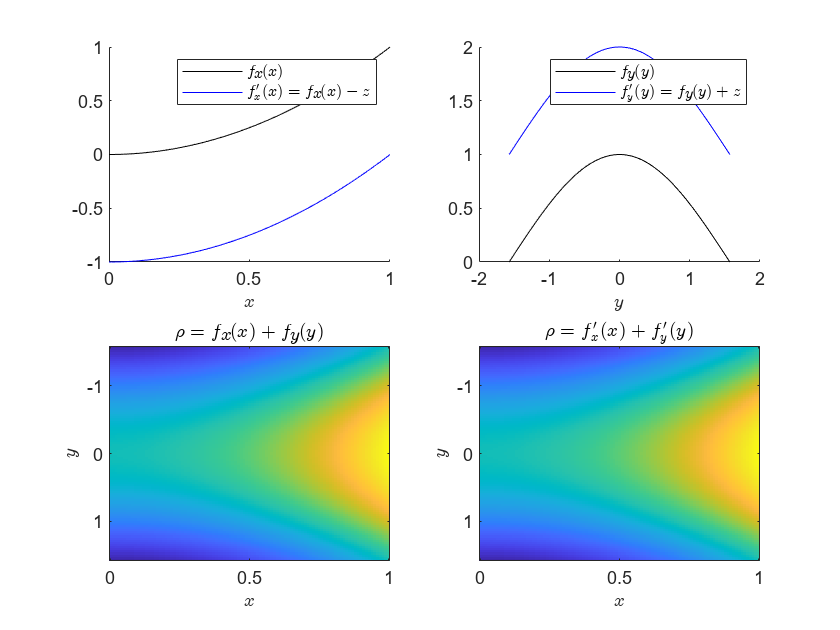

illustrate_shift_invariance;

This property creates a class of equivalent solution $(f_x-z,f_y+z)$ which makes the model unidentifiable from data. Note that the problem is exactly the same when using categorical regressors `cat(x)` instead of nonlinear mapping `f(x). `Although the prior on weights (which are in a way a soft constraint on weights) may help to identify a single solution, the best practice is to remove this unidentifiability problem in the likelihood by adding a **hard constrainst on the set of weight**. For example we can add the constraint that $f_x(0)=0$. In general we will use linear constraints on the set of weights.

The second type of indeterminacy (invariance to scale) arises when we use regressor multiplication such as $\rho = f_x(x)f_y(y)$. Here I can divide $f_x(x)$ by a fixed scalar $z \neq 0$ and multiply $f_y(y)$ by that same scalar $z$ and obtain exactly the same predictor $\rho$, since $\frac{f_x(x)}z (f_y(y)z) = f_x(x)f_y(y)$. Again this indeterminacy can be lifted by adding a hard constraint on one of the two functions, for example $f_x(0)=1$. 

When declaring a formula, the GUM toolbox automatically adds linear constraints on the set of weights in order to avoid these issues.

For **categorical variables** (i.e. `cat(x)`), one of the categories is taken as the reference category (by default the first value in numerical or alphabetical order). The reference category can be changed using `cat(x;ref=lbl) `where `lbl` is the corresponding label. The value of the weight for the reference category is constrained to be null to avoid the shift invariance. If the regressor is multiplied with another regressor, e.g. `cat(x)*f(y)`, then the value of the weight for the reference category is constrained to be 1 to avoid the scale invariance.

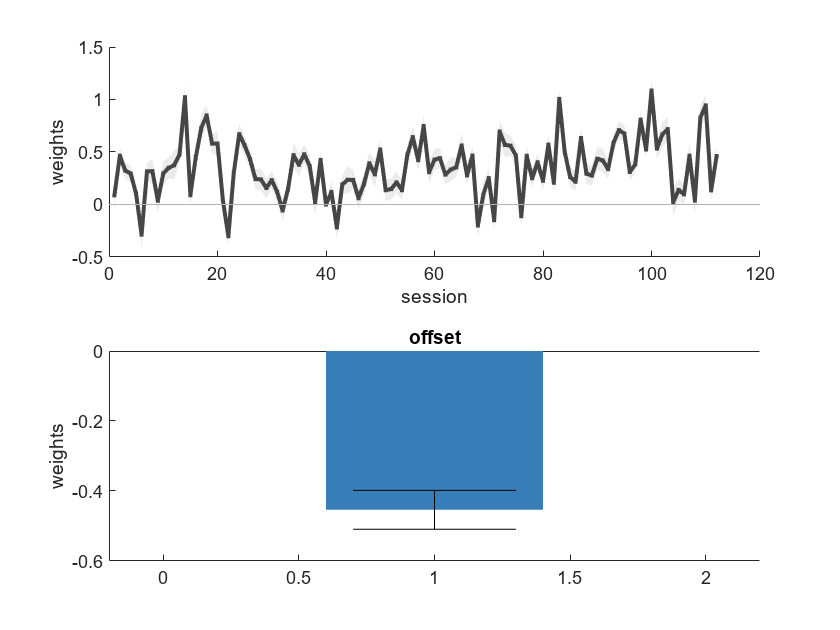

M = gum(T, 'resp ~ cat(session; ref=40)').infer('verbose','off');
figure; M.plot_weights;

For nonlinear mapping of **continuous variables **(i.e. `f(x)`):

- by default the function has no hard constraint (i.e. in the formula '`y~x1+f(x2)'`)

- if the formula sums more than one nonlinear function, then all functions but the first one are associated with a '`nullsum`' constraint (i.e. the sum of $f(x_i$) over all values $x_i$ taken in the dataset if constrained to be null).

- when nonlinear functions are multiplied, as in `f(x1)*f(x2)`, then the first function has no constraint while the second has '`mean1'` constraint (i.e. the average value of the function is constrained to be 1).

### Design matrix

After creating your model `M, y`ou can plot the design matrix (i.e. the value of all regressors for all observations) using `M.plot_design_matrix()`.

Use `M.plot_design_matrix(subset) `to plot the design matrix for a subset of observations (`subset` should be a vector of indices or logical array).

When using basis functions, use `M.project_to_basis.plot_design_matrix(...) `to plot the design matrix in the space of basis functions instead of the original space (i.e. if you use a polynomial of order 3 you will see 3 columns corresponding to each power).

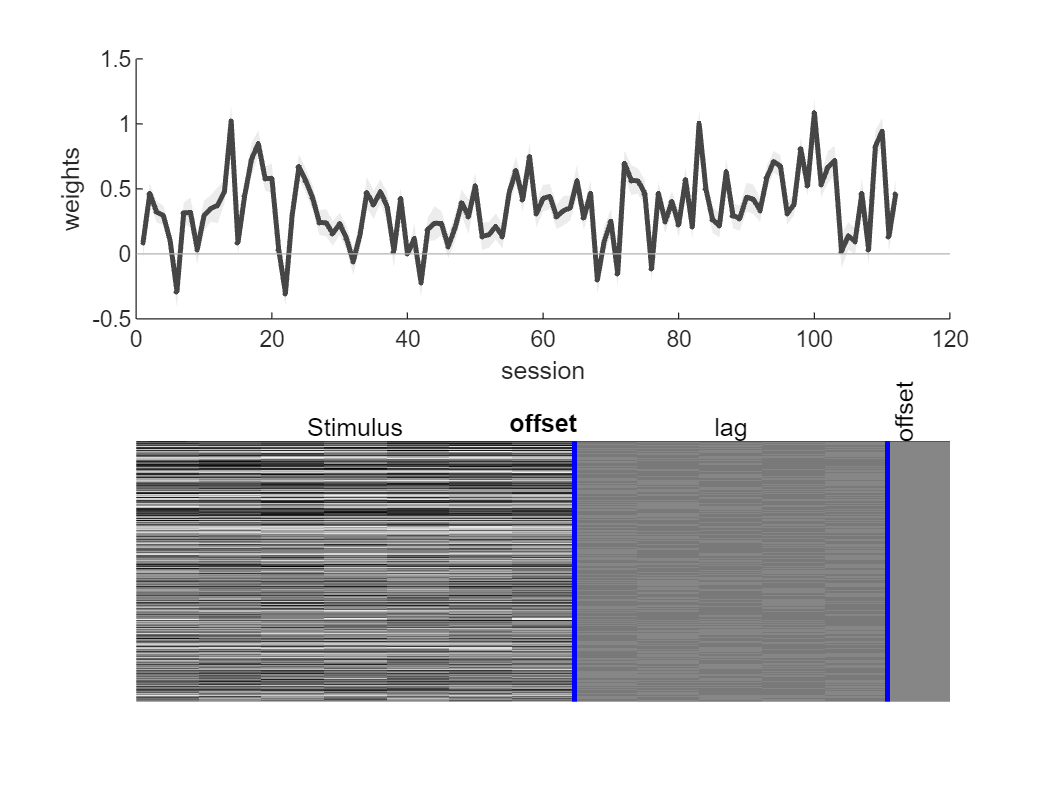

fmla = 'resp ~ Stimulus  + lag(response; Lags=1:5)';
M = gum(T, fmla);
M.plot_design_matrix;

function illustrate_shift_invariance()
x = 0:.01:1;
y = pi*(-.5:.01:.5)';
f_x = x.^2;
f_y = cos(y);
z = 1;
f_x_prime = f_x - z;
f_y_prime = f_y + z;
figure;
subplot(2,2,1); hold on;
plot(x, f_x,'k');
plot(x, f_x_prime,'b');
xlabel('$x$','interpreter','latex');
legend({'$f_x(x)$','$f_x''(x)=f_x(x) - z$'},'interpreter','latex');
subplot(2,2,2); hold on;
plot(y, f_y,'k');
plot(y, f_y_prime,'b');
xlabel('$y$','interpreter','latex');
legend({'$f_y(y)$','$f_y''(y)=f_y(y) + z$'},'interpreter','latex');
subplot(2,2,3);
rho = f_x + f_y;
imagesc(x, y, rho);
title('$\rho = f_x(x)+f_y(y)$','interpreter','latex');
xlabel('$x$','interpreter','latex'); ylabel('$y$','interpreter','latex');
subplot(2,2,4);
rho = f_x_prime + f_y_prime;
imagesc(x, y, rho);
title('$\rho = f_x''(x)+f_y''(y)$','interpreter','latex');
xlabel('$x$','interpreter','latex'); ylabel('$y$','interpreter','latex');
end